clc;clear;close all;
num_1=4000; % the number of positive roots
H=0.042690748412273;
bm=[];
bm1=[];
bm2=[];
syms x;

parfor j=0:num_1-1
    b(j+1)=vpasolve(tan(x*H)==x/(x^2-0.25),3.1415926/H*j);
    bm(j+1)=double(b(j+1));
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 3 4 5 7 8 10 13 14 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 12 workers.


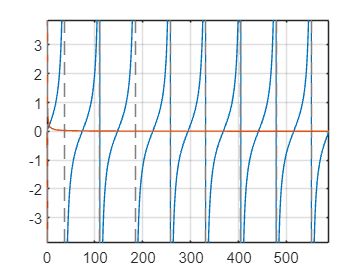

bm_cw=[0,bm(1,1:length(bm)-1)];
bm_c=bm-bm_cw;

while max(bm_c)>3.1415926/H+3.1415926/H/50
    for i=1:length(bm)-1
        if bm(i+1)-bm(i)>3.1415926/H+3.1415926/H/50
            bm0=vpasolve(tan(x*H)==x/(x^2-0.25),[bm(i)+3.1415926/H/50 bm(i+1)-3.1415926/H/50]);
            bm1(i)=double(bm0);
            if bm1(i)>bm(i)+3.1415926/H/50 && bm1(i)<bm(i+1)-3.1415926/H/50
                bm=[bm,bm1(i)];
            end
        end
        bm=sort(bm);
    end
    bm_cw=[0,bm(1,1:length(bm)-1)];
    bm_c=bm-bm_cw;
end
for i=1:length(bm)-1
    if bm(i+1)-bm(i)>3.1415926/H+3.1415926/H/50
        disp(bm(i));
    end
end


for i=1:length(bm)-1
    if bm(i+1)-bm(i)>3.1415926/H/50

        bm2=[bm2,bm(i)];

    end
end
bm=bm2;
for i=1:length(bm)-1
    if bm(i+1)-bm(i)<3.1415926/H/50
        disp(bm(i));
    end
end

bm_sup=vpasolve(tan(x*H)==x/(x^2-0.25),x,[0+3.1415926/H/50 bm(2)-3.1415926/H/50],'Random',true);
bm_sup=double(bm_sup);
if ~isempty(bm_sup)
    if bm_sup>0+3.1415926/H/50 && bm_sup<bm(2)-3.1415926/H/50
        bm=[bm,bm_sup];
    end
end
bm=sort(bm);
% Image of transcendental equation
fplot(tan(x*H),[0 bm(10)])
hold on;
fplot(x/(x^2-0.25),[0 bm(10)])
grid on;


for i=1:length(bm)-1
    if bm(i+1)-bm(i)>3.1415926/H+3.1415926/H/50
        disp([num2str(bm(i)),'of line',num2str(i),'is wrong'])

    end
end
% Save the file to the current folder
fid = fopen('bm.txt','wt');
fprintf(fid,'%f\n',bm); 
fclose(fid);